% Import instron CSV data 
instron_data_1 = readtable("StepStrainSweepPressure2_1.csv");

instron_data_2 = readtable("StepStrainSweepPressure2_2.csv");

instron_data_3 = readtable("StepStrainSweepPressure2_3.csv");

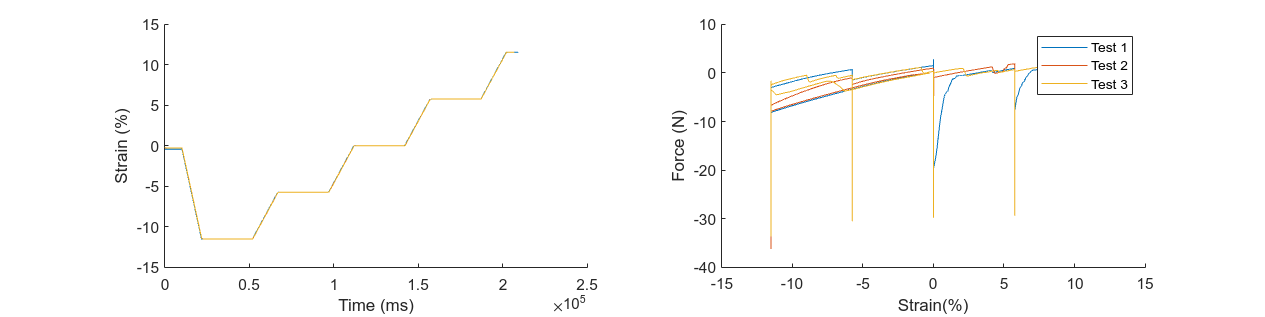

instron_data_tables = {instron_data_1, instron_data_2, instron_data_3};

fig = figure();
set(fig, "Position", [0, 0, 1600, 400])
subplot(1, 2, 1);
hold on;
for i = 1 : length(instron_data_tables)
    plot(instron_data_tables{i}.Time, instron_data_tables{i}.TensileStrain_Displacement_);
end
xlabel("Time (ms)")
ylabel("Strain (%)")

subplot(1, 2, 2);
hold on
for i = 1 : length(instron_data_tables)
    plot(instron_data_tables{i}.TensileStrain_Displacement_, instron_data_tables{i}.Force);
end
xlabel("Strain(%)");
ylabel("Force (N)")
legend(["Test 1", "Test 2", "Test 3"]);